M =     2.3713    1.1548    0.6643


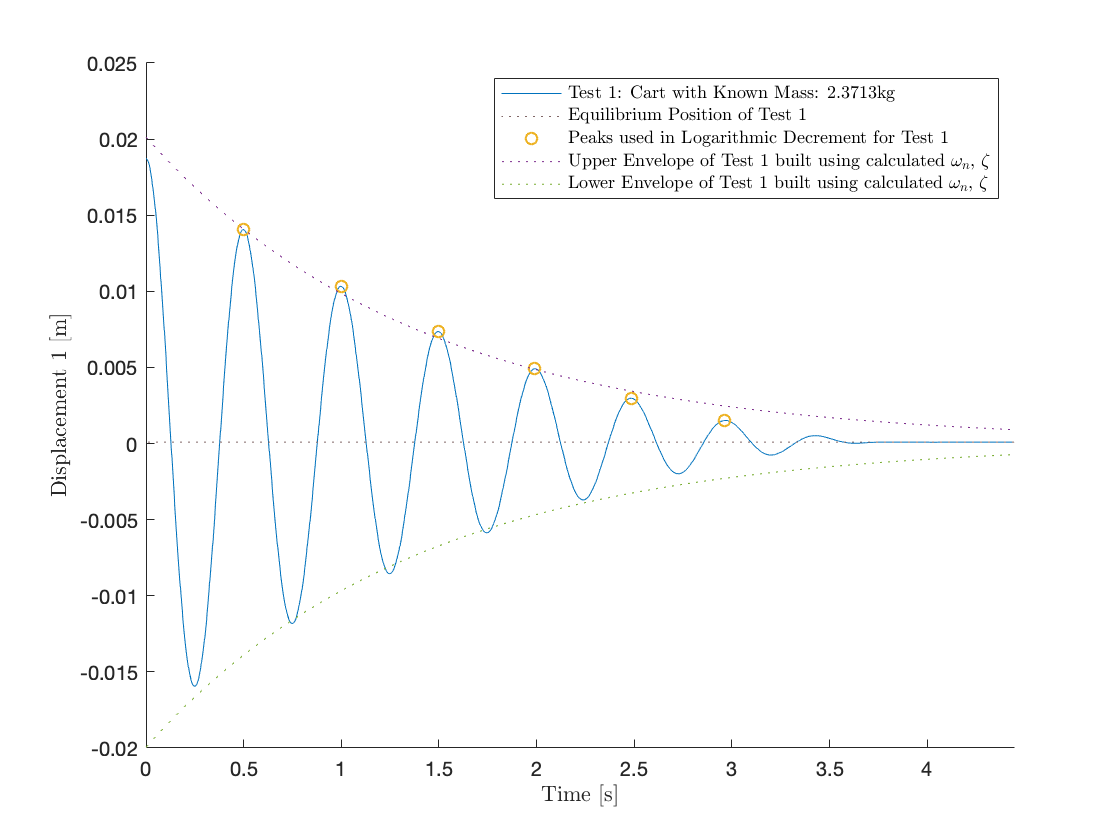

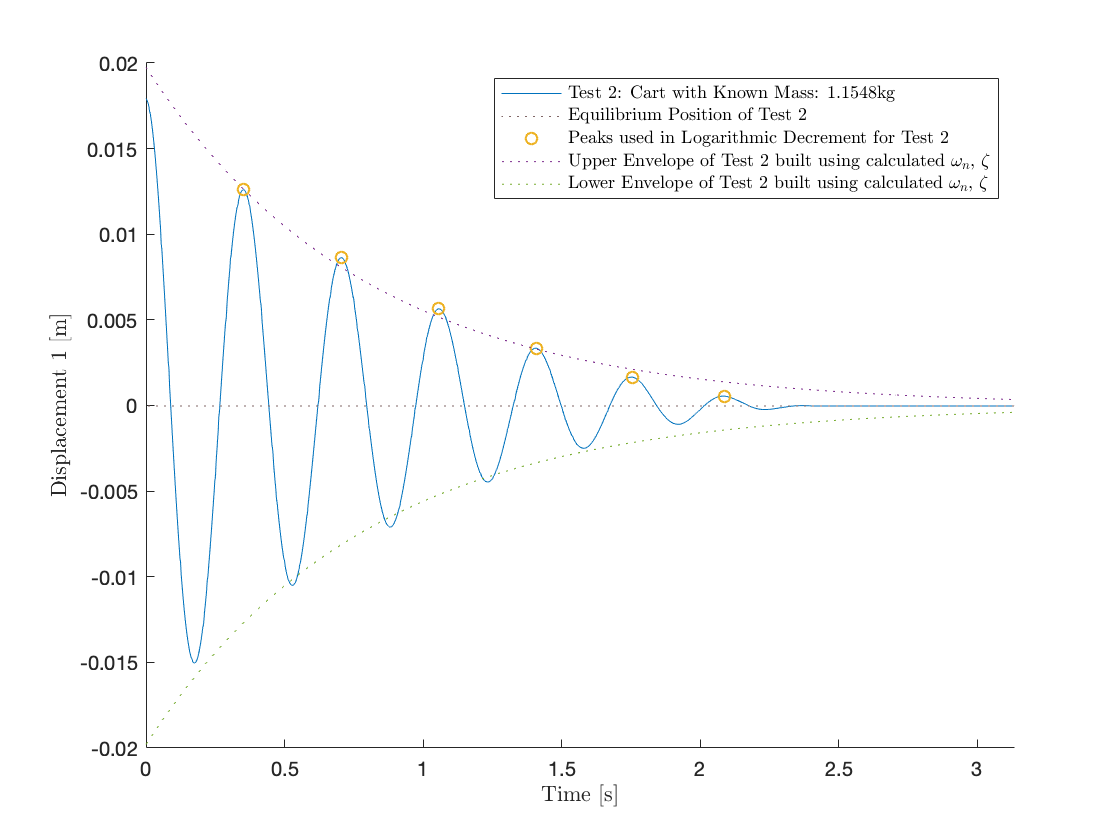

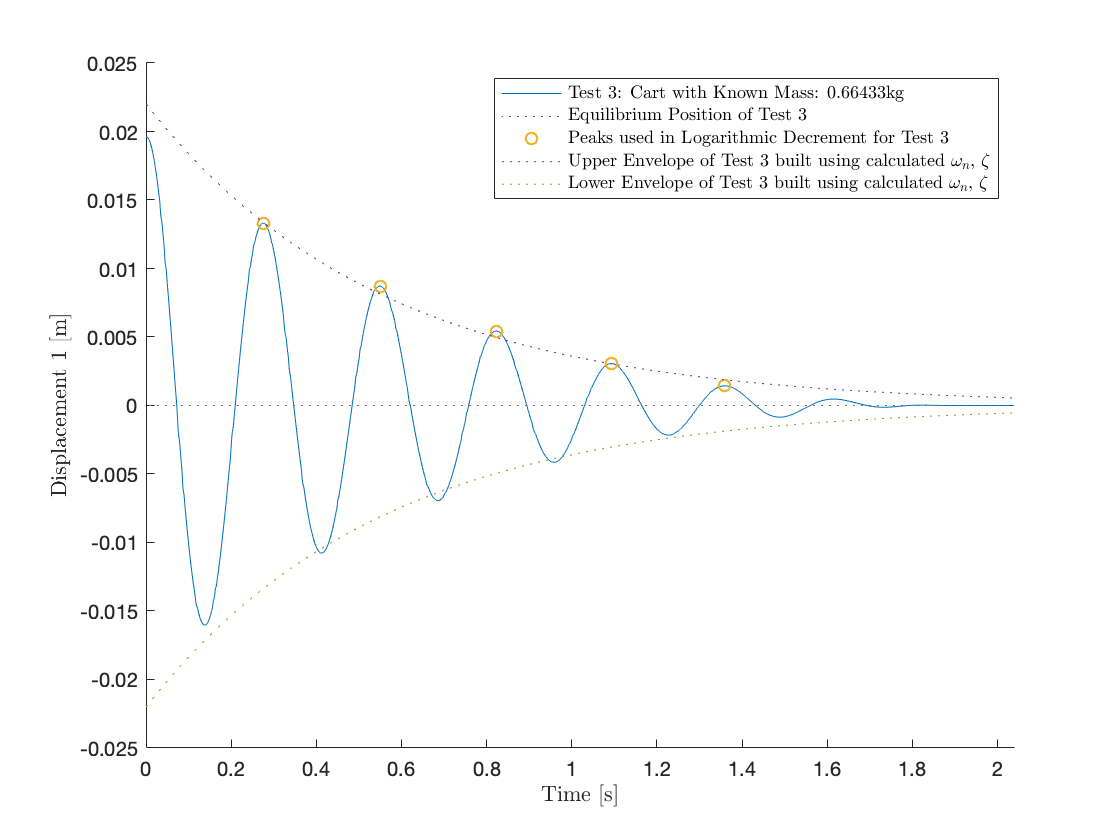

wn =    12.7754   18.1410   23.2772


z =     0.0563    0.0698    0.0778


k =   387.0292  380.0525  359.9551


c =     3.4130    2.9266    2.4074


ans = 375.6790

ans = 2.9157

rect_q5_run()

function rect_q5_run()
    % PRIOR KNOWNS:
    % Masses of Blocks [kg]:
    mb1 = 490.5e-3; 
    mb2 = 485.5e-3;
    mb3 = 240.5e-3;
    mb6 = 490.5e-3;
    Mc = mean([0.768, 0.672, 0.553]); % Mean of Cart Masses Determined in Lab 1
    
    % Known Masses for Each Experiment:
    M(1) = Mc + mb1 + mb2 + mb3 + mb6;
    M(2) = Mc + mb1;
    M(3) = Mc
    
    % Perform Logarithmic Decrement on All Experiments:
    for i = 1:3
        [wn(i), z(i), ~, ~, t_end] = multi_logdec("m", "RectData/exp2/3.1/", i, "test"+i, M(i)+"kg");
        xlim([0 t_end(1)])
        saveas(gcf, char("Rect_q5-"+i+".png"), 'png');
    end
    %Display Logarithmic Decrement Results:
    disp("wn: " + wn);
    disp("z: " + z);
    
    % Compute All Unknowns:
    k = wn.^2 .* M
    c = 2 .* z .* wn .* M
    mean(k)
    mean(c)
end